# Example 6.29: Detection of Water Contaminants (0.05 nM SDS)

Note: this script reproduces the second part of Example 6.29 (Section 6.7.2) of **Statistics for Chemical Engineers**: detecting a much lower SDS concentration. Shiyi (Amy) Qin and Victor Z UW-Madison, 2024 use CNN for classifying LC droplet micrographs: no SDS vs 0.05 nM SDS (case II)

clc; clear all; close all hidden;

% load data: X is 256 x 256 x 3 x 100 (color micrographs), y is the label (0 = no SDS, 1 = SDS)
load('Data/lc_sds_caseII.mat')
X = double(X)/255;                 % scale pixel values to [0,1]
Y = categorical(y, [0 1], {'no SDS', '0.05 nM SDS'});

% split data: 80 images for training and 20 for validation (same proportion of each class)
rng(0);
cv = cvpartition(Y, 'HoldOut', 0.2);
XTrain = X(:,:,:,training(cv)); YTrain = Y(training(cv));
XValidation = X(:,:,:,test(cv)); YValidation = Y(test(cv));

% define CNN architecture: one convolutional layer with 2 3x3 filter(s) and ReLU activation
layers = [
    imageInputLayer([256 256 3], 'Normalization', 'none')  % height, width, and channel size

    convolution2dLayer(3, 2, 'Padding', 'same')
    reluLayer

    fullyConnectedLayer(2)          % fully connected layer has 2 classes
    softmaxLayer
    classificationLayer
    ];

## Training

train CNN

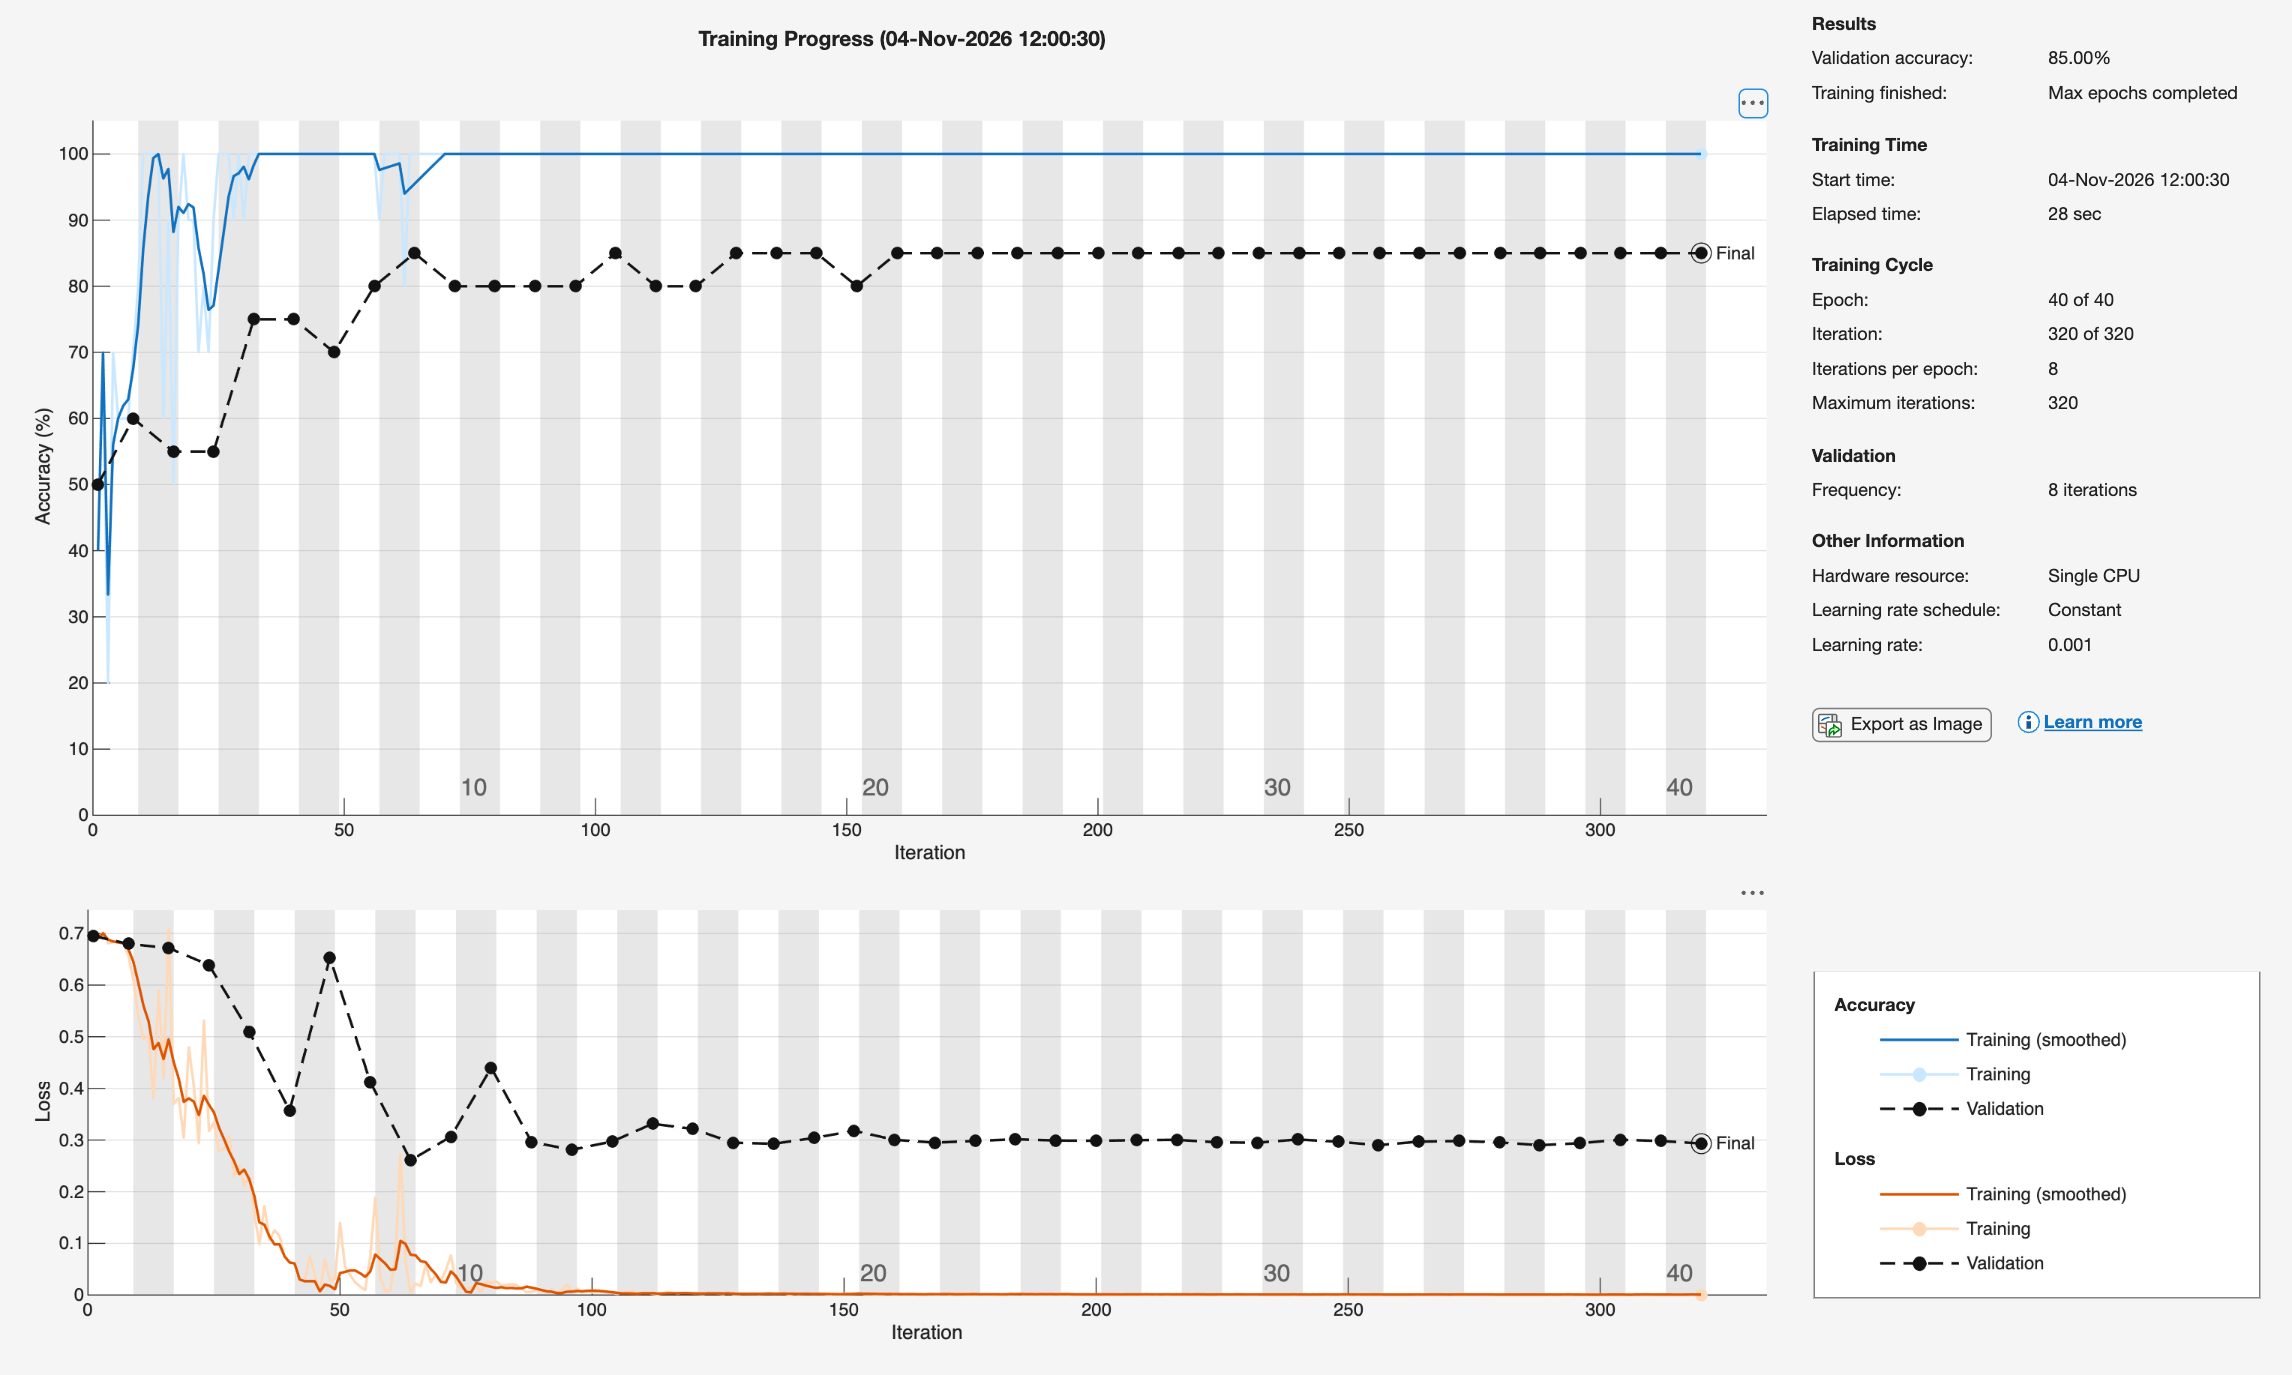

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs', 40, ...
    'MiniBatchSize', 10, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {XValidation, YValidation}, ...
    'ValidationFrequency', 8, ...
    'Verbose', false, ...
    'Plots', 'training-progress');

net = trainNetwork(XTrain, YTrain, layers, options);

## Accuracy

obtain training accuracy

YPredT = classify(net, XTrain);
accuracyTrain = sum(YPredT == YTrain)/numel(YTrain)

accuracyTrain = 1


% obtain validation accuracy
YPredV = classify(net, XValidation);
accuracyValidation = sum(YPredV == YValidation)/numel(YValidation)

accuracyValidation = 0.8500

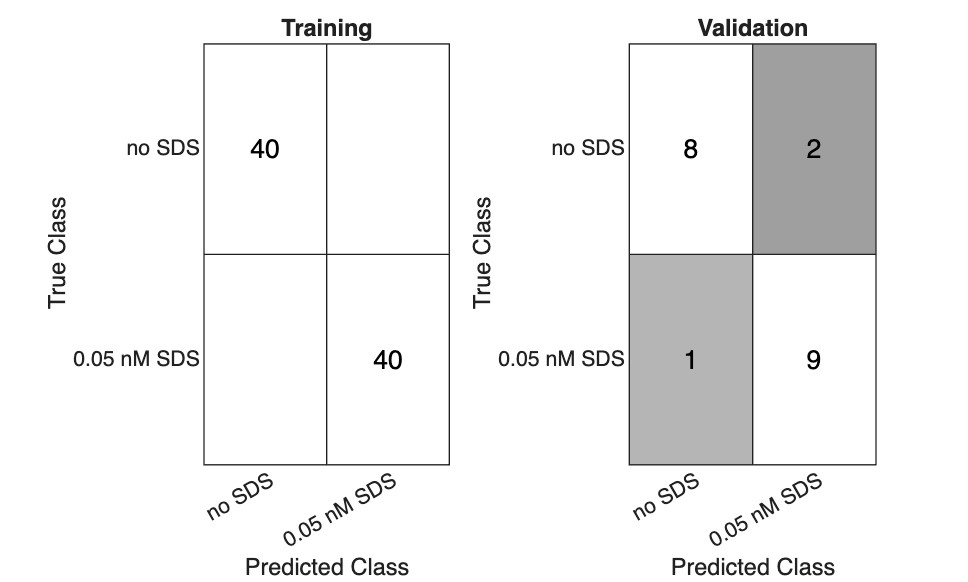


% confusion matrices
figure(2)
subplot(1,2,1)
confusionchart(YTrain, YPredT, 'DiagonalColor', [1 1 1], 'OffDiagonalColor', [0 0 0]);
title('Training')
subplot(1,2,2)
confusionchart(YValidation, YPredV, 'DiagonalColor', [1 1 1], 'OffDiagonalColor', [0 0 0]);
title('Validation')
print -depsc ch6_lcdroplet_sds_confusion_caseII.eps


% display filters
net.Layers(2).Weights

ans = 3×3×3×2 single array
ans(:,:,1,1) =
   -0.2439    0.0253   -0.1672
    0.2189   -0.2389    0.1199
   -0.1347    0.0800    0.1453
ans(:,:,2,1) =
    0.1955   -0.1814    0.2557
   -0.0219    0.3180    0.0460
   -0.2922   -0.2393    0.3783
ans(:,:,3,1) =
   -0.3032    0.3448    0.2414
   -0.0376   -0.3556    0.2784
   -0.2855    0.2056   -0.2965
ans(:,:,1,2) =
   -0.0621   -0.0402   -0.1507
   -0.1674    0.3065   -0.2443
    0.2278   -0.2215   -0.2509
ans(:,:,2,2) =
    0.2814   -0.2469   -0.0881
    0.0670    0.2676    0.0238
    0.0461    0.1001   -0.0569
ans(:,:,3,2) =
   -0.2950   -0.2212   -0.2982
   -0.1853   -0.1821    0.3051
   -0.2668   -0.0501    0.3351

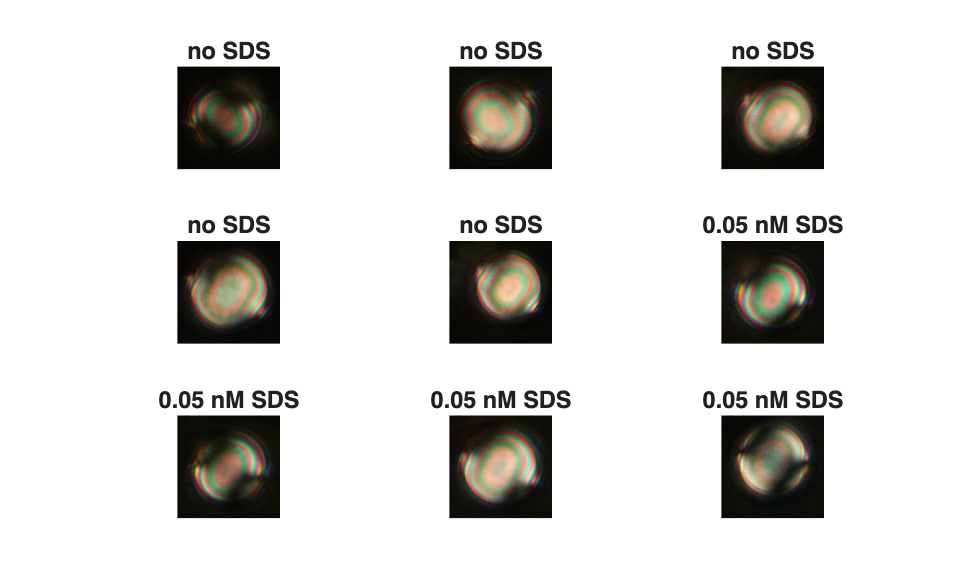


% display some of the images in the validation set (both classes)
cats = categories(Y);
idx = [find(YValidation == cats{1}, 5); find(YValidation == cats{2}, 4)];
figure(1)
for i = 1:9
    subplot(3,3,i);
    imshow(XValidation(:,:,:,idx(i)));
    title(char(YValidation(idx(i))))
end
print -depsc ch6_lcdroplet_sds_data_caseII.eps

## Activations

get activations of the convolutional layer (first filter)

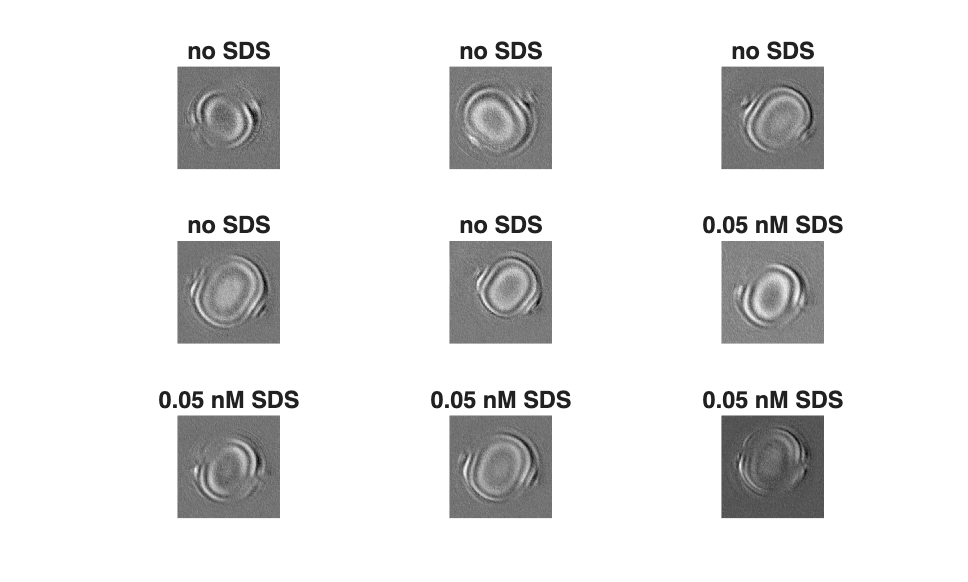

Act = activations(net, XValidation, 2);

figure(3)
for i = 1:9
    subplot(3,3,i)
    imshow(rescale(Act(:,:,1,idx(i))))
    title(char(YValidation(idx(i))))
end
print -depsc ch6_lcdroplet_sds_activations_caseII.eps

## Note

As in the book, the validation accuracy is about 80%: detecting contaminants at lower concentrations is significantly harder, yet the CNN still finds nonobvious patterns.